# **EllipticB**

Complete and incomplete Jacobi form of the elliptic integral B 

## Definition 

**Incomplete elliptic integral B**


$$\mathit{\mathbf{B}}\left(x\left|m\right.\right)\equiv \int_0^x \sqrt{\frac{1-\;t^2 }{1-mt^2 }}\;\textrm{dt}$$



$$\mathit{\mathbf{B}}\left(x,k\right)\equiv \mathit{\mathbf{B}}\left(x\left|k^2 \right.\right)$$


Domain: $1-x^2 \ge 0$ and $1-mx^2 \ge 0$. If $-\infty <m\le 1$  (or $|k|\le 1$) then $-1\le x\le 1$. If $m>1$ (or $k>1$) then  $|x|<1/\sqrt{m}$. For the specified domain, the  codomain  is the set of real numbers.

Basic features:

$\mathit{\mathbf{B}}\left(-x\left|m\right.\right)=-\mathit{\mathbf{B}}\left(x\left|m\right.\right)$   (odd)

Special values:

$\mathit{\mathbf{B}}\left(0\left|m\right.\right)=0$,   $\mathit{\mathbf{B}}\left(1\left|m\right.\right)=B\left(m\right)$

$\mathit{\mathbf{B}}\left(x\left|-\infty \right.\right)=0$,   $\mathit{\mathbf{B}}\left(x\left|0\right.\right)=\frac{1}{2}\left(\sin^{-1} \left(x\right)+x\sqrt{1-x^2 }\right)$,   $\mathit{\mathbf{B}}\left(x\left|1\right.\right)=x$

Identities:


$$\mathit{\mathbf{B}}\left(x\left|m\right.\right)=B\left(\sin^{-1} \left(x\right)\left|m\right.\right),\;\;\;\;\left|x\right|\le 1$$



$$\mathit{\mathbf{B}}\left(x\left|m\right.\right)=\frac{\mathit{\mathbf{E}}\left(x\left|m\right.\right)-\left(1-m\right)\mathit{\mathbf{F}}\left(x\left|m\right.\right)}{m}$$



$$\mathit{\mathbf{B}}\left(x\left|m\right.\right)=\frac{\mathit{\mathbf{E}}\left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}},\;\;m>1$$


$B\left(\phi \left|m\right.\right)$ is Legendre form of the elliptic integral *B*. $\mathit{\mathbf{E}}\left(x\left|m\right.\right)$, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ are the Jacobi form of elliptic integrals of the first and of the second kind.

**Complete elliptic integral B**


$$B\left(m\right)\equiv \mathit{\mathbf{B}}\left(1\left|m\right.\right)=B\left(\frac{\pi }{2}\left|m\right.\right)$$



$$\mathit{\mathbf{B}}\left(k\right)\equiv B\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $1-m\ge 0$, (or $|k|\le 1$). For the specified domain, the  codomain is real numbers.

Special values:

$B\left(-\infty \right)=0,$   $B\left(0\right)=\frac{\pi }{4}$,   $B\left(1\right)=1$

## Syntax

**Incomplete integral**

Y = EllipticB(X,K)

y = elB(x,k)

Y = mEllipticB(X,M)

y = melB(x,m)

**Complete integral**

Y = EllipticB(K)

y = elB(k)

Y = mEllipticB(M)

y = melB(m)

## Description

**Incomplete integral**

**Y = EllipticB(X,K)** returns the Jacobi form of the elliptic integral  $\mathit{\mathbf{B}}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **EllipticB** is the wrapper function which calls the functions **elB** element-wise via the function **ufun2**.

**y = elB(x,k)** returns  value of the Jacobi form of the elliptic integral  $\mathit{\mathbf{B}}\left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **elB** is the wrapper function which calls the functions **melB**.

**Y = mEllipticB(X,M) **returns the Jacobi form of the elliptic integral  $\mathit{\mathbf{B}}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mEllipticB** is the wrapper function which calls the functions **melB** element-wise via the function **ufun2**.

**y = melB(x,m)** compute the value of the Jacobi form of the elliptic integral  $\mathit{\mathbf{B}}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **melB **call the Carlson's functions **rf **and** rd **for calculation of $\mathit{\mathbf{B}}\left(x\left|m\right.\right)$ ([1-2]).

**Complete integral**

**Y = EllipticB(K) **returns the value of the complete elliptic integral $\mathit{\mathbf{B}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticB** is the wrapper function which calls the functions **elB** element-wise via the function **ufun1**.

**y = elB(k)** returns the value of the complete elliptic integral  $\mathit{\mathbf{B}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elB** is the wrapper function which calls the functions **melB**.

**Y = mEllipticB(M)** returns the value of  the complete elliptic integral $B\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticB** is the wrapper function which calls the functions **melB** element-wise via the function **ufun1**.

**y = melB(m)** compute value of  the complete elliptic integral  $B\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melB **call the function **mcelB **which call the Carlson's functions **rf **and** rd** for calculation of $B\left(m\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
x = 0.5;
[elB(x,k), EllipticB(x,k), melB(x,k^2), mEllipticB(x,k^2)]

ans =    0.483241858284035   0.483241858284035   0.483241858284035   0.483241858284035


[elB(k), EllipticB(k), melB(k^2), mEllipticB(k^2)]

ans =    0.812597772919921   0.812597772919921   0.812597772919921   0.812597772919921


m = 0.5; % |m|<1 
[elB(sqrt(m)), EllipticB(sqrt(m)), melB(m), mEllipticB(m)]

ans =    0.847213084793979   0.847213084793979   0.847213084793979   0.847213084793979


Accuracy

melB(0.02) % =0.7874 (Jahnke, Emde, 1945, pp 82)

ans = 0.7874

melB(0.52)  % =0.8504 (Jahnke, Emde, 1945, pp 82)

ans = 0.8504

melB(0.94) % % =0.9583 (Jahnke, Emde, 1945, pp 82)

ans = 0.9582

Accuracy. 

fprintf('%.16g\n',melB(1/4,-4)) % Maple 18D   0.2381514800971605 32

0.2381514800971605


fprintf('%.16g\n',melB(1/2)) % Maple 18D   .8472130847939790 8

0.8472130847939792


Special values

m = -2;
x = -0.5;  % |x| <= 1
melB(0,m)

ans = 0

disp(melB(1,m) - melB(m))  % m < 1 !!!

     0



melB(x,-inf)

ans = 0

disp(melB(x,0) - (asin(x) + x*sqrt(1 - x^2))/2)

     0



disp(melB(x,1) - x)

     0



melB(x,-inf)  

ans = 0

melB(-inf)

ans = 0

disp(elB(0) - pi/4)

     0



disp(elB(1)-1)

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
mEllipticB(-x,m) + mEllipticB(x,m)

ans = 0

disp(mEllipticB(x,m) - mpEllipticB(asin(x),m))

     0



k = 0.99995;
disp(EllipticB(x,k) - (EllipticE(x,k) - (1 - k^2)*EllipticE(x,k))/k^2)

    -4.930444300665915e-06



m = 0.99995;
x = 0.5;
disp(mEllipticB(x,m) - (mEllipticE(x*sqrt(m),1/m)/sqrt(m)))

    -5.551115123125783e-17



**Vector input**

m = [1, 2, 3]';
x = 0.5;
disp(mEllipticB(x,m) - (mEllipticE(x.*sqrt(m),1./m)./sqrt(m)))

   1.0e-15 *

                   0
  -0.111022302462516
                   0



**Matrix input**

m = [1, 2, 3; 4, 5, 6]';
x = 0.25;
disp(mEllipticB(x,m) - (mEllipticE(x.*sqrt(m),1./m)./sqrt(m)))

   1.0e-15 *

                   0   0.055511151231258
  -0.055511151231258   0.055511151231258
  -0.111022302462516   0.055511151231258



## **Plot **

**Example 1**

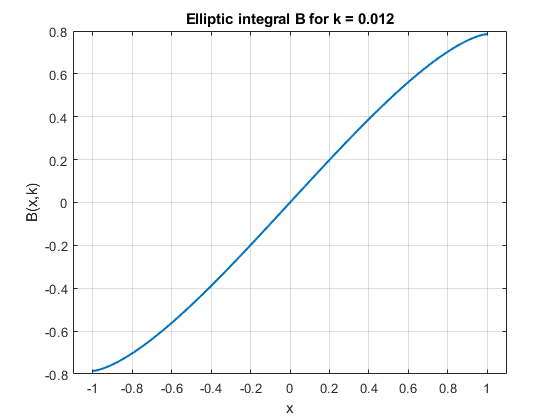

figure
x=-1:0.01:1;
k = 0.012;
plot(x,EllipticB(x,k),'LineWidth',1.5)
xlabel('x')
ylabel('B(x,k)')
xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral B for k = %g',k))
grid on

**Example 2**

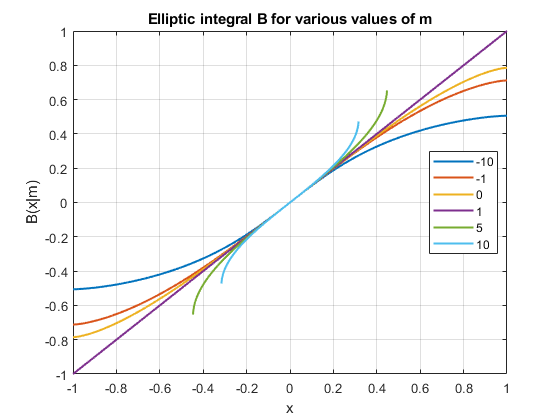

figure
X = -1:0.001:1;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mEllipticB(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1 1])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral B for various values of m')
xlabel('x')
ylabel('B(x|m)')

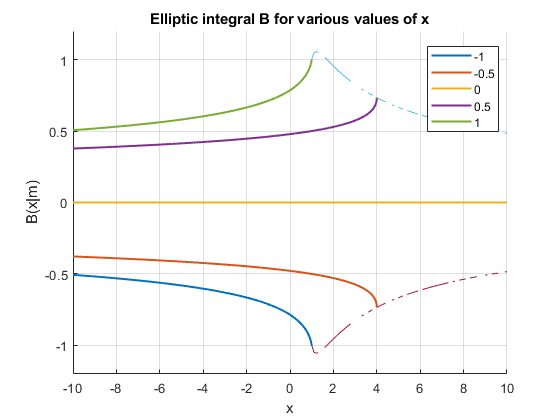

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticB(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -1.2 1.2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral B for various values of x')
xlabel('x')
ylabel('B(x|m)')
M = 0:0.1:10;
E = mEllipticB(1./sqrt(abs(M)),M);
plot(M,E)
plot(M,-E)
hold off

**Example 3**

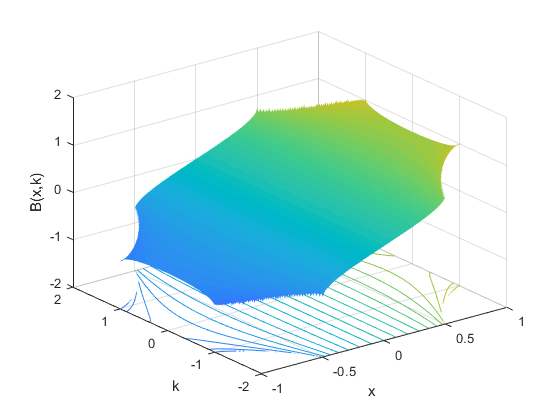

figure
x=-1:0.01:1;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,EllipticB(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('B(x,k)')
zlim([-2 2])
grid on

**Example 4**

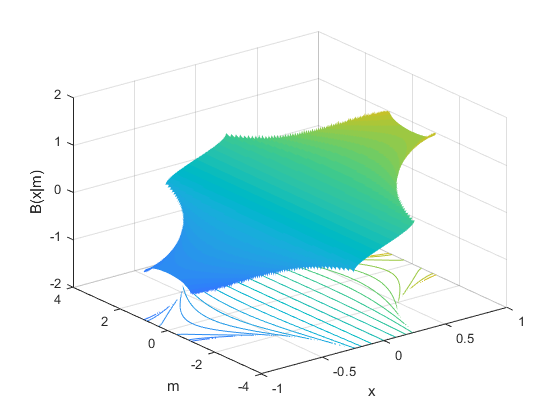

figure
x=-1:0.01:1;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,EllipticB(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -2;
hc.LineWidth = 0.5;
hc.LevelList = -2:0.1:2;
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('B(x|m)')
zlim([-2 2])
grid on

**Example 5**

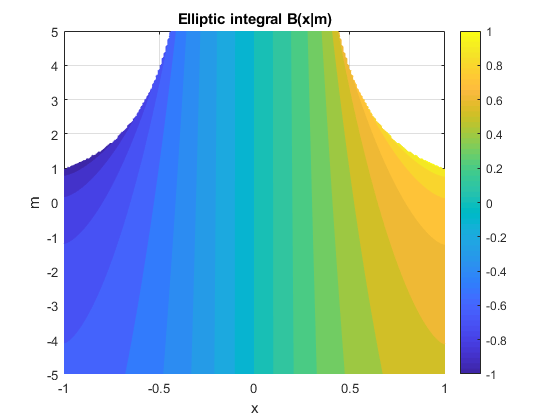

figure
f = @(x,m)mEllipticB(x,m);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral B(x|m)')
xlabel('x')
ylabel('m')
colorbar
grid on

**Example 6**

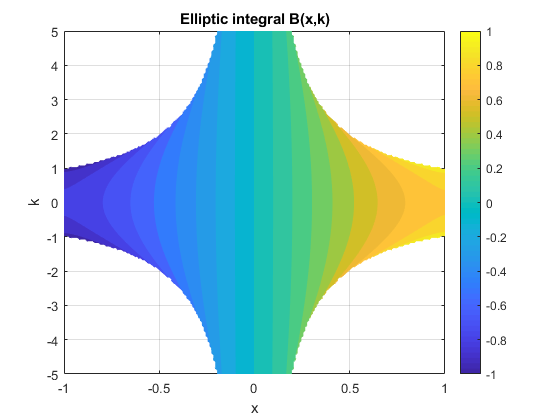

figure
f = @(x,k)EllipticB(x,k);
fcontour(f,[-1 1 -5 5],'Fill','on','LevelList',-1:0.1:1,'MeshDensity',200)
title('Elliptic integral B(x,k)')
xlabel('x')
ylabel('k')
colorbar
grid on

**Example 7**

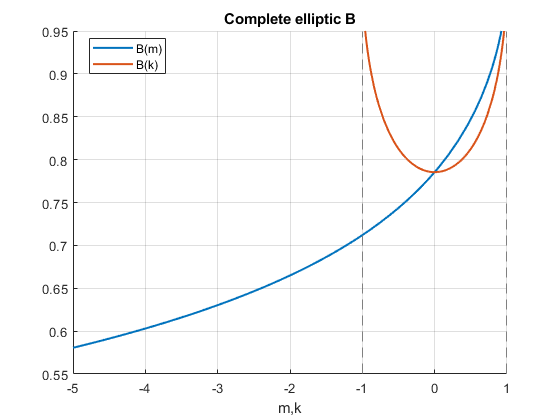

figure
hold on
fplot(@(m) mEllipticB(m),'LineWidth',1.5)
fplot(@(k) EllipticB(k),'LineWidth',1.5)
title('Complete elliptic B')
legend('B(m)','B(k)','Location','best')
xlabel('m,k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also